# Quarter wave plate

A quarter-wave plate is a bi-refringent material cut to a specific thickness.  The bi-refringence produces two rays: ordinary and extraordinary.  These rays are polarized at 90 deg difference, so that we can treat one as oscillating in the x- and the other in the y-direction.

The bi-refringent material has different index of refraction (speed of light) for the two rays. If we cut the thickness of the plate correctly, then one is delayed compared to the other.  By setting the thickness precisely, we can treat one in sine phase and the other in cosine phase.

The first figure produced in this script shows the two rays oscillating in the x- and y-directions as the red markers. The sum of the two is shown as the end point on the black line (whose origin is at 0,0). Notice that the amplitude is constant. The direction changes around in a circle over time.  Hence the quarter-wave plate produces a ray with circular polarization.

With an LC we can shift the relative retardation by different amounts as we apply a voltage across the LC.  This produces circular, elliptical, or linear polarizations.  The next two graphs show the examples. 

Imagine, then, we read the output by a linear polarizer in the -45 deg direction.  You can see that the amplitude in that direction varies as we change the phase retardation.

## Set up the two waves as a quarter wave

% Oscillating wave representing a ray polarized in the x-direction
t = (0:2:255)/256;
f = 2;
ordinaryW = sin(2*pi*f*t);
% plot(t,ordinaryW);

% Oscillating wave representing polarization in the y-direction
extraordinaryW = sin(2*pi*f*t - pi/2);
% plot(t,extraordinaryW);

total = [ordinaryW(:), extraordinaryW(:)];

## Make the movie

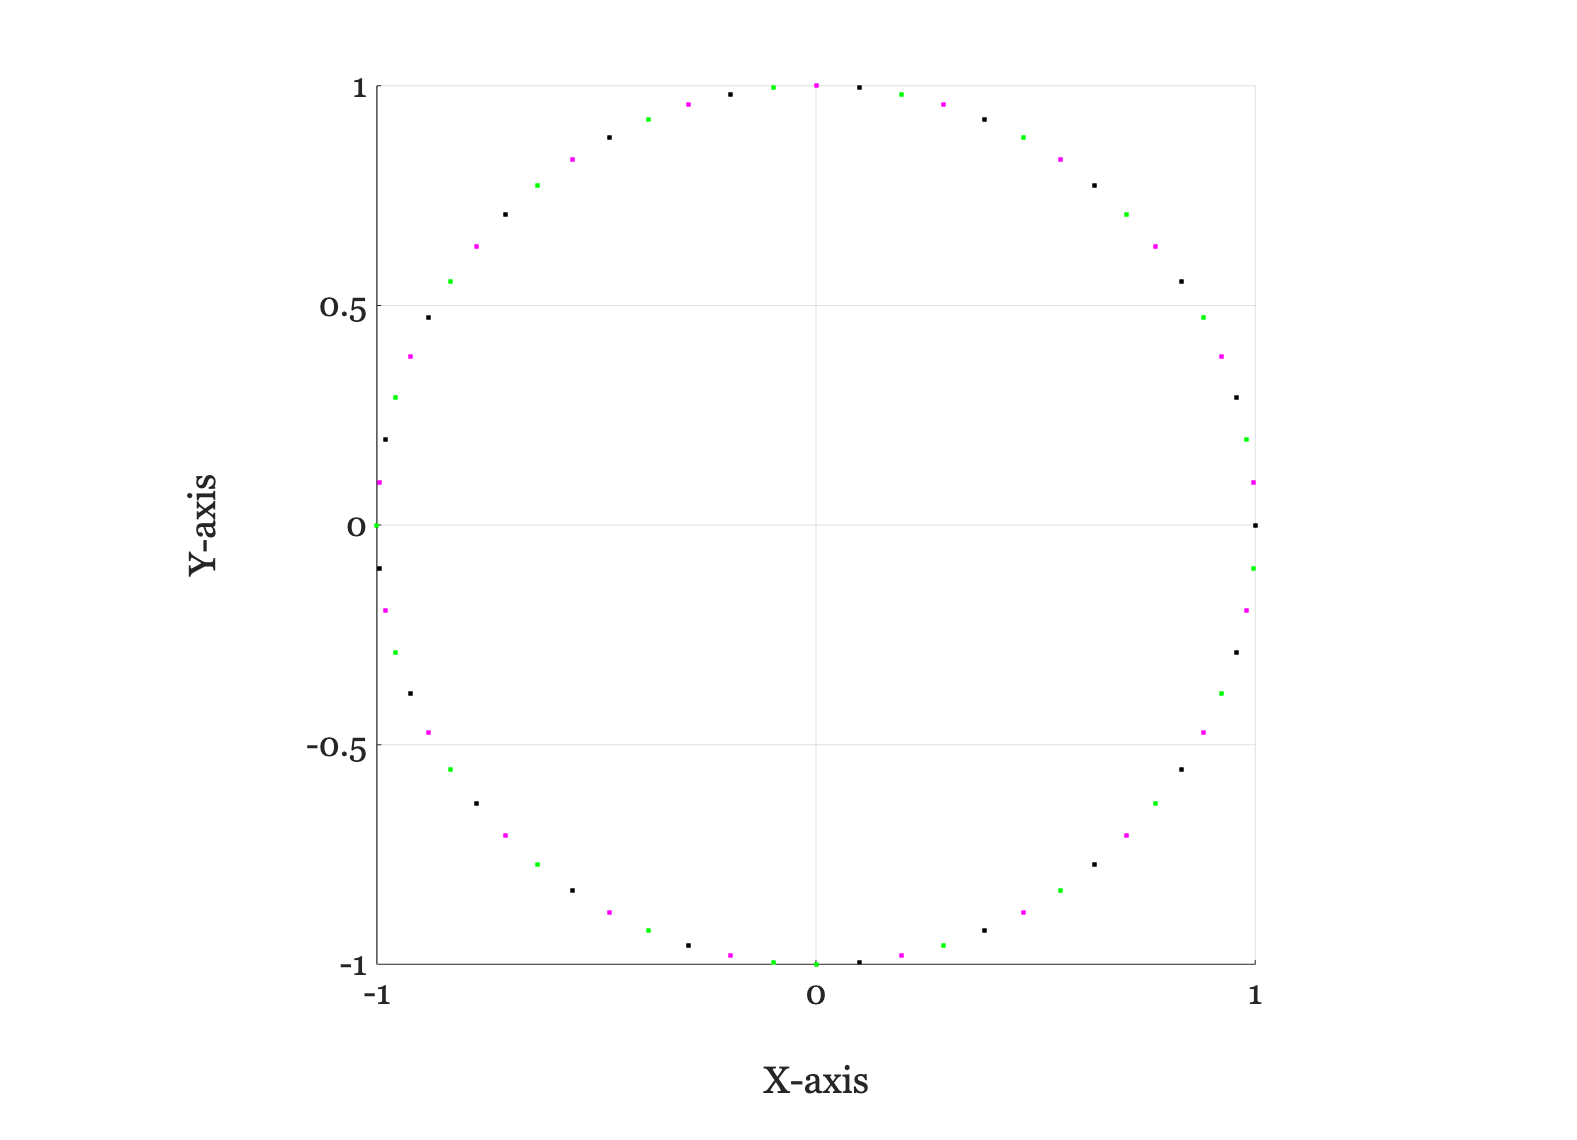

ieNewGraphWin; axis equal; grid on;
xlabel('X-axis'); ylabel('Y-axis');

% For each moment in time, plot the individual rays as red markers and
% the sum as the black line.
for ii=1:numel(t)
    % cla;   
    l = line([0 total(ii,1)],[0 total(ii,2)],...
        'Color','k','LineWidth',2); hold on;
    p1 = plot(total(ii,1),0,'rx','MarkerSize',14); hold on;
    p2 = plot(0,total(ii,2),'ro','MarkerSize',14); hold on;
    plot(total(ii,1),total(ii,2),'.'); hold on;
    set(gca,'xlim',[-1 1],'ylim',[-1 1]);
    pause(0.05); delete(l); delete(p1); delete(p2);
end

## Shift the retardation - as we might with an LC

extraordinaryW = sin(2*pi*f*t - pi/4);
total = [ordinaryW(:), extraordinaryW(:)];

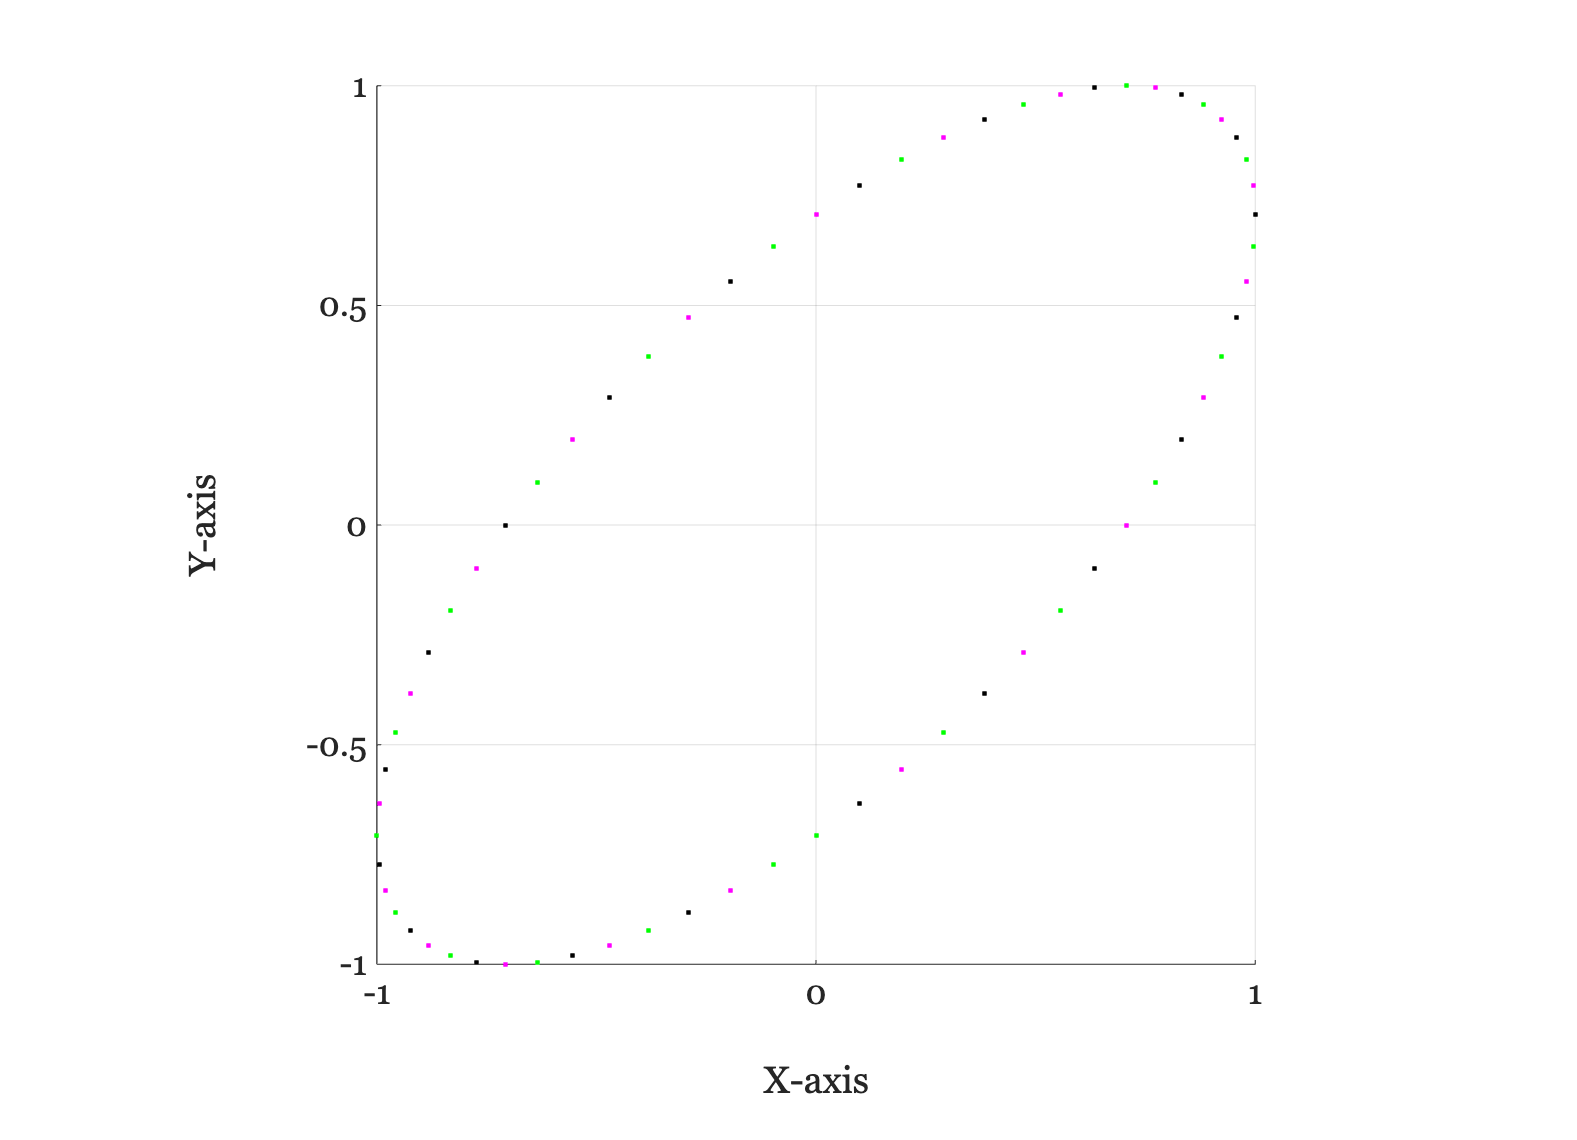

ieNewGraphWin; axis equal; grid on;
xlabel('X-axis'); ylabel('Y-axis');

% For each moment in time, plot the individual rays as red markers and
% the sum as the black line.
for ii=1:numel(t)
    % cla;   
    l = line([0 total(ii,1)],[0 total(ii,2)],...
        'Color','k','LineWidth',2); hold on;
    p1 = plot(total(ii,1),0,'rx','MarkerSize',14); hold on;
    p2 = plot(0,total(ii,2),'ro','MarkerSize',14); hold on;
    plot(total(ii,1),total(ii,2),'.'); hold on;
    set(gca,'xlim',[-1 1],'ylim',[-1 1]);
    pause(0.05); delete(l); delete(p1); delete(p2);
end

## Shift the retardation again - half wave

extraordinaryW = sin(2*pi*f*t - pi);
total = [ordinaryW(:), extraordinaryW(:)];

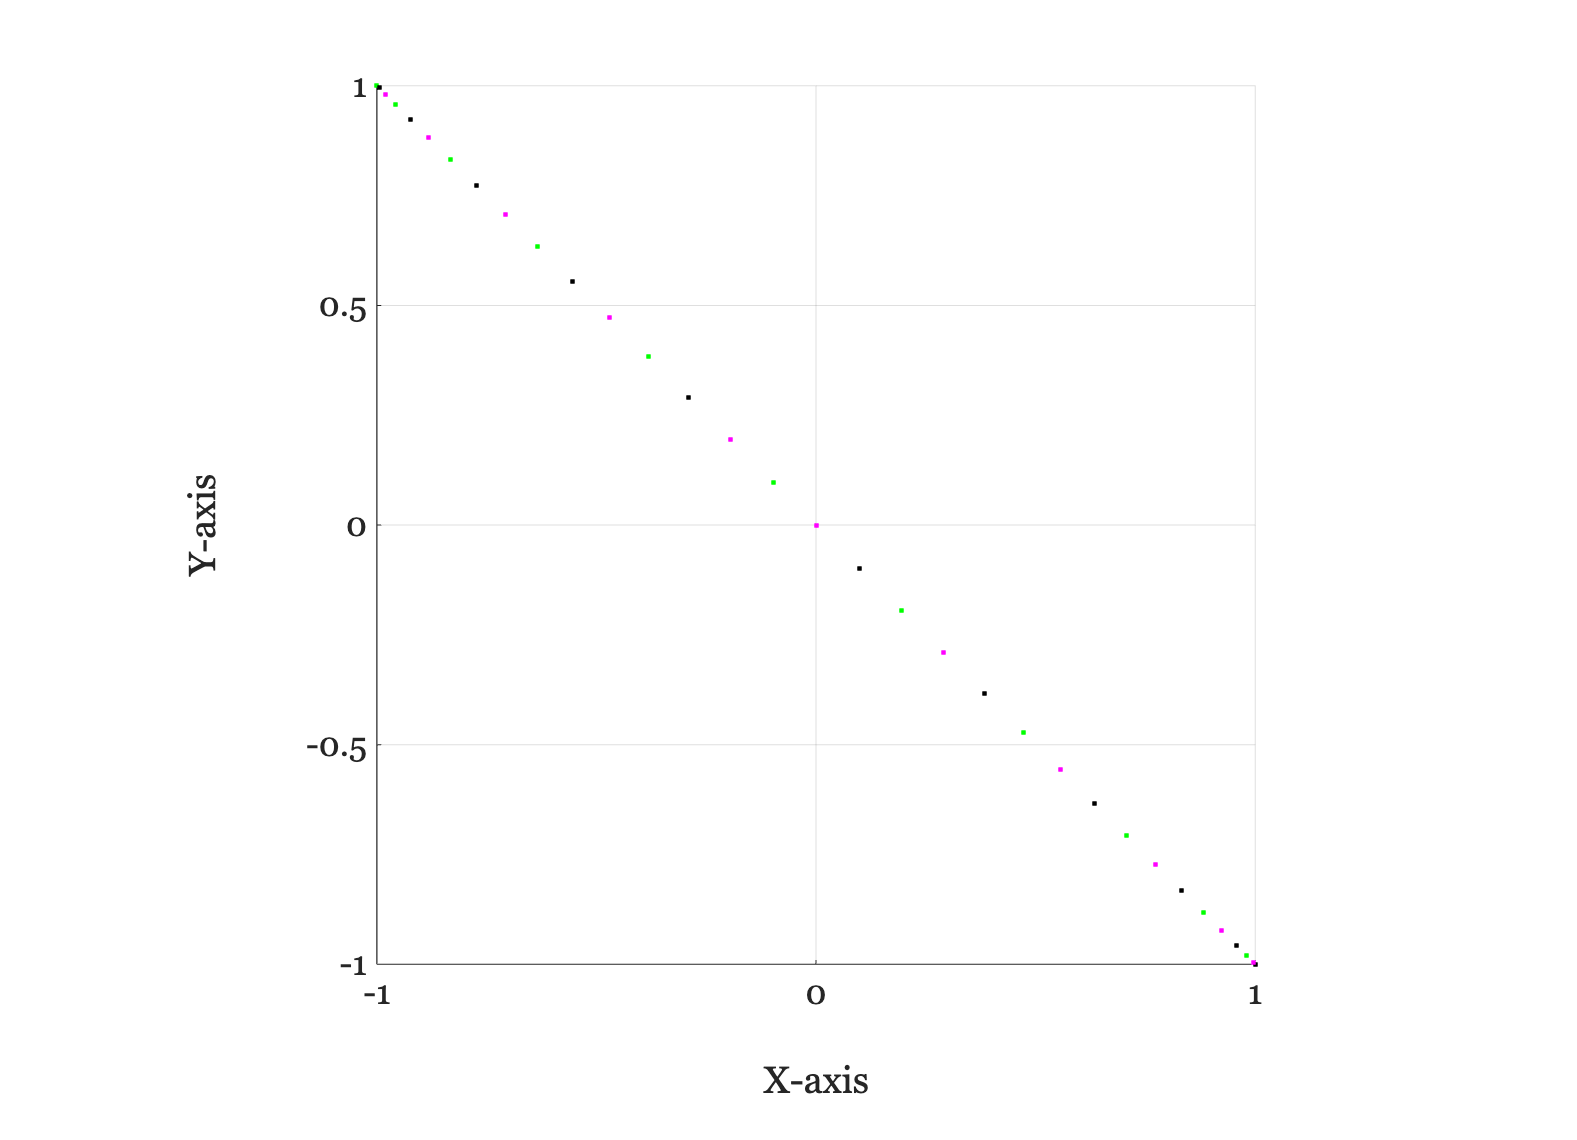

ieNewGraphWin; axis equal; grid on;
xlabel('X-axis'); ylabel('Y-axis');

% For each moment in time, plot the individual rays as red markers and
% the sum as the black line.
for ii=1:numel(t)
    % cla;   
    l = line([0 total(ii,1)],[0 total(ii,2)],...
        'Color','k','LineWidth',2); hold on;
    p1 = plot(total(ii,1),0,'rx','MarkerSize',14); hold on;
    p2 = plot(0,total(ii,2),'ro','MarkerSize',14); hold on;
    plot(total(ii,1),total(ii,2),'.'); hold on;
    set(gca,'xlim',[-1 1],'ylim',[-1 1]);
    pause(0.05); delete(l); delete(p1); delete(p2);
end